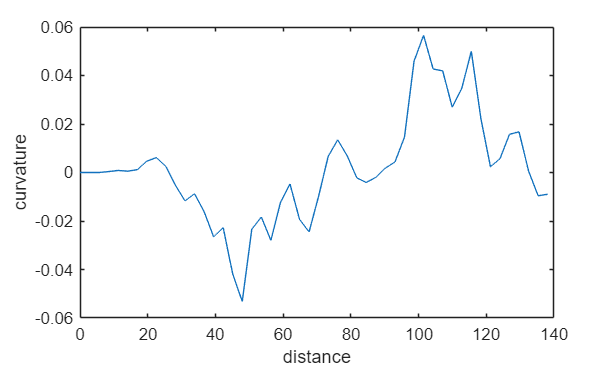

clc; clearvars;
setUpModel


velt_res = 8;
x0 = X_o; y0 = Y_o; psi0 = psi_o;
L = 3; LD = 2;
xRef = xRef2s; yRef = yRef2s;
Tpp = totalDistance / velt_res;
StopTime = Tpp;

Kgain = 2.5;                                 % pôvodný zisk kinematického Stanleyho
Kvals = [2.5 4 6 8 12 16 18 20];

fprintf('Spustam simulacie...\n');

Spúšťam simulácie...


out_kin = sim('stanleySimple_kin2', 'StopTime', num2str(StopTime));

out_dyn = sim('stanleySimple2', 'StopTime', num2str(StopTime));

out_pp  = sim('zadanie_Vutianov_Kyrylova', 'StopTime', num2str(Tpp));
fprintf('Simulácie úspešne dokončené.\n');

Simulácie úspešne dokončené.



%% Zber dát
x_kin = extractPose(out_kin, 'poseKin', 1);  y_kin = extractPose(out_kin, 'poseKin', 2);
x_dyn = extractPose(out_dyn, 'poseDyn', 1);  y_dyn = extractPose(out_dyn, 'poseDyn', 2);
x_pp = getPoseData(out_pp, 'x'); x_pp = x_pp(:);
y_pp = getPoseData(out_pp, 'y'); y_pp = y_pp(:);

%% Metriky
sD = linspace(0, totalDistance, 3000);
xD = interp1(gradbp, xRef2s, sD); yD = interp1(gradbp, yRef2s, sD);
cte = @(x,y) cteU(x, y, xD, yD);
rmse = @(e) sqrt(mean(e.^2));

e_kin = cte(x_kin,y_kin); e_dyn = cte(x_dyn,y_dyn); e_pp = cte(x_pp,y_pp);

%% ladenie zisku kinematického Stanleyho
R = zeros(size(Kvals)); M = zeros(size(Kvals));
for j = 1:numel(Kvals)
    Kgain = Kvals(j);
    o = sim('stanleySimple_kin2', 'StopTime', num2str(StopTime));
    e = cte(extractPose(o,'poseKin',1), extractPose(o,'poseKin',2));
    R(j) = rmse(e); M(j) = max(e);
end

disp(table(Kvals(:), R(:), M(:), 'VariableNames', {'k','RMSE_m','Max_m'}))

     k     RMSE_m      Max_m 
    ___    _______    _______

    2.5    0.65926     1.3574
      4    0.51785     1.1009
      6    0.43447    0.93881
      8    0.39166     0.8533
     12    0.34776    0.76874
     16    0.32514    0.72757
     18    0.31737    0.71346
     20    0.31111    0.70285




[~,b] = min(R);  Kbest = Kvals(b);
fprintf('Najlepšie k = %g\n', Kbest);

Najlepšie k = 20



Kgain = Kbest;
out_kin2 = sim('stanleySimple_kin2', 'StopTime', num2str(StopTime));

x_kin2 = extractPose(out_kin2,'poseKin',1);
y_kin2 = extractPose(out_kin2,'poseKin',2);
e_kin2 = cte(x_kin2, y_kin2);

%% Tabuľka
T = table(["Stanley kin";"Stanley dyn";"Pure Pursuit";"Stanley kin vylepšený"], ...
    [rmse(e_kin);rmse(e_dyn);rmse(e_pp);rmse(e_kin2)], ...
    [max(e_kin);max(e_dyn);max(e_pp);max(e_kin2)], ...
    'VariableNames', {'Algoritmus','RMSE_m','Max_m'});
disp(T)

          Algoritmus            RMSE_m      Max_m 
    _______________________    ________    _______

    "Stanley kin"               0.65926     1.3574
    "Stanley dyn"               0.40181    0.91435
    "Pure Pursuit"             0.054887    0.13688
    "Stanley kin vylepšený"     0.31111    0.70285



fprintf('Pokles RMSE: %.1f %%\n', (rmse(e_kin)-rmse(e_kin2))/rmse(e_kin)*100);

Pokles RMSE: 52.8 %


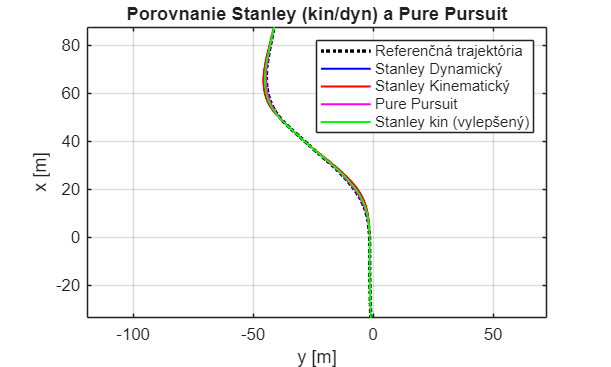


%% Graf
figure('Name', 'Porovnanie riadenia vozidla', 'Color', 'w');
plot(yRef2s, xRef2s, 'k:', 'LineWidth', 2); hold on;
plot(y_dyn,  x_dyn,  'b-', 'LineWidth', 1.2);
plot(y_kin,  x_kin,  'r-', 'LineWidth', 1.2);
plot(y_pp,   x_pp,   'm-', 'LineWidth', 1.2);
plot(y_kin2, x_kin2, 'g-', 'LineWidth', 1.2);
grid on; axis equal;
xlabel('y [m]'); ylabel('x [m]');
title('Porovnanie Stanley (kin/dyn) a Pure Pursuit');
legend('Referenčná trajektória','Stanley Dynamický','Stanley Kinematický', ...
       'Pure Pursuit','Stanley kin (vylepšený)','Location','northeast');
exportgraphics(gcf, 'porovnanie.png', 'Resolution', 300);


%% Diagnostika maximálnej chyby
nm = {'Stanley kin','Stanley dyn','Pure Pursuit','Stanley kin vylepšený'};
P  = {[x_kin y_kin],[x_dyn y_dyn],[x_pp y_pp],[x_kin2 y_kin2]};
for q = 1:4
    [e,xu,yu] = cte(P{q}(:,1), P{q}(:,2));
    [m,i] = max(e);
    fprintf('%-22s max = %.3f m v bode x=%.1f, y=%.1f\n', nm{q}, m, xu(i), yu(i));
end

Stanley kin            max = 1.357 m v bode x=63.8, y=-45.8
Stanley dyn            max = 0.914 m v bode x=64.0, y=-45.4
Pure Pursuit           max = 0.137 m v bode x=58.5, y=-43.7
Stanley kin vylepšený  max = 0.703 m v bode x=61.1, y=-44.9


fprintf('Najlepšie k = %g\n', Kbest);

Najlepšie k = 20



%% Pomocné funkcie 
function D = getPoseData(out, nm)
    names = out.who;
    if any(strcmp(names, nm)),            v = out.get(nm);
    elseif any(strcmp(names, ['out.' nm])), v = out.get(['out.' nm]);
    else
        error('Premenna %s sa nenasla. Dostupne: %s', nm, strjoin(names(:)', ', '));
    end
    if isa(v, 'timeseries'), D = v.Data; else, D = v; end
    if ndims(D) == 3, D = squeeze(D).'; end              
    if size(D,2) ~= 3 && size(D,1) == 3, D = D.'; end    
end

function coord = extractPose(out_sim, blockName, colIdx)
    data = getPoseData(out_sim, blockName);
    coord = data(:, colIdx);
end

function [e, xu, yu] = cteU(x, y, xD, yD)
 x = x(:); y = y(:);
 s = [0; cumsum(hypot(diff(x), diff(y)))];
 [s, k] = unique(s);
 su = linspace(0, s(end), 1000)';
 xu = interp1(s, x(k), su); yu = interp1(s, y(k), su);
 e = min(pdist2([xu yu], [xD(:) yD(:)]), [], 2);
end